# ACCOMPLISH: ODE Solvers

Dr. Zheng Chen, Mathematics Department, University of Massachusetts Dartmouth 

## Goal:

The goal of this module is to finish building a graphical user interface (GUI) MATLAB to solve initial value problems of ordinary differential equations (ODEs).  Here is how the GUI looks:

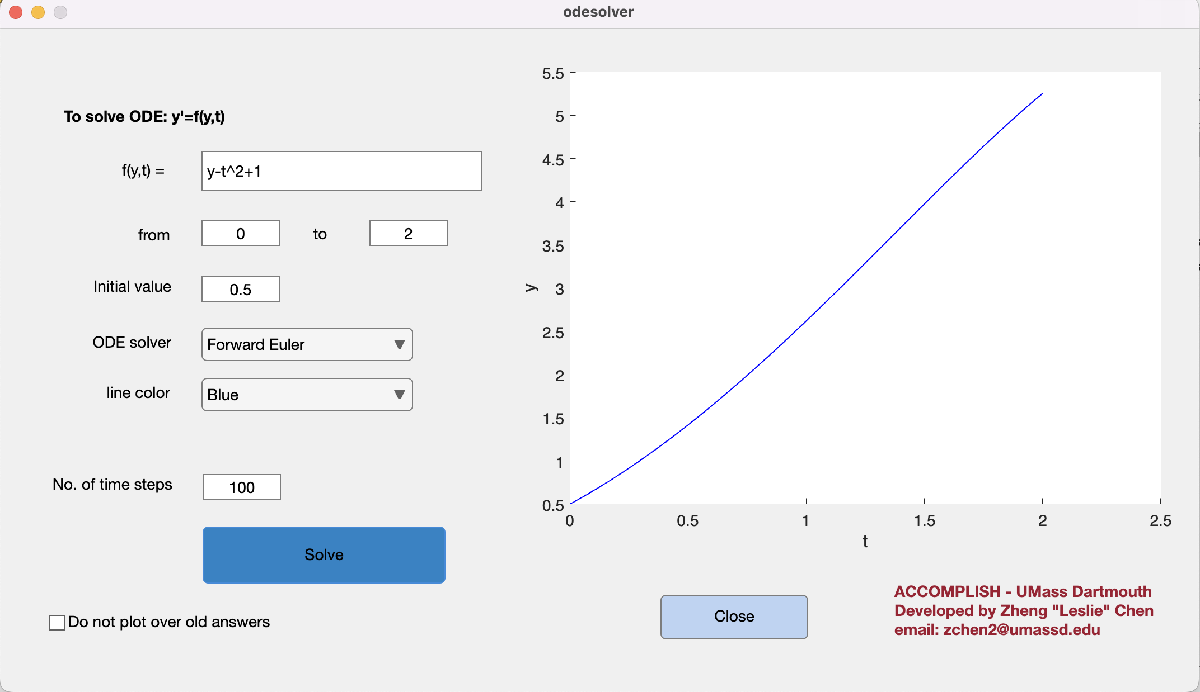

The user will input the formula of the right hand side function $f(y,t)$, the range of time $t$, and choose a numerical ODE solver to approximate the solution $y(t)$.  The framework of this GUI is provided to students in the app file "**odesolver_App.mlapp**" with several unfinished "**.m**" files (one for each solver).  The full version is provided to the advisor, and the students will work on the student version with blank parts of codes in the "**.m**" files. 

**The student's mission** is to study different numerical methods for ODEs and finish the functions for each method.  The blank parts are under the "**.m**" files for solvers.  More details will be shown later under each method. 

**Resources for GUI in MATLAB:**

- [Recommended] How to Build a GUI in MATLAB using **App Designe**r [https://youtu.be/nb0jHVXKY2w](https://youtu.be/nb0jHVXKY2w)

- [Previous tool, about to be removed] How to Create a GUI with **GUIDE** [https://www.mathworks.com/videos/creating-a-gui-with-guide-68979.html](https://www.mathworks.com/videos/creating-a-gui-with-guide-68979.html)

There are many numerical methods for ODEs.  In this GUI, the following methods are included: 

- **Forward Euler**

- **Taylor Method (choose order)**

- **second-order Runge-Kutta Method - Midpoint method**

- **second-order Runge-Kutta Method - Modified Euler method**

- **second-order Runge-Kutta Method - Heun's method**

- **Runge-Kutta Method of order 4**

- **Matlab ode45**

- **Matlab ode15s**

- **Matlab ode23**

- **Matlab ode23s**

- **Matlab ode23t**

- **Matlab ode113**

No. 7~12 are MATLAB built-in functions, and the students do not need to code for these solvers. The GUI has potential to be expanded to include other methods as well. 

## **1. **Initial-Value Problems for Ordinary Differential Equations 

The general form ofd **first-order IVP**:


$$\[
(IVP)\quad
\begin{cases}
y'(t)&=&f(t,y),&\quad a\le t\le b,\\
y(a)&=&\alpha.
\end{cases}
\]$$


### Well-posedness

**Definition**: The initial-value problem 


$$\[
(IVP)\quad
\begin{cases}
y'(t)&=&f(t,y),&\quad a\le t\le b,\\
y(a)&=&\alpha
\end{cases}
\]$$


is **well-posed**, if

- There exists a unique solution y(t) to the problem.

- There exists constants $\epsilon_0 > 0, k > 0$ such that for any $0<\epsilon<\epsilon_0$, whenever $|\delta(t)|<\epsilon$ for all $t \in [a,b]$ and $\delta_0<\epsilon$, the perturbed initial problem	 


$$\[
(IVP)\quad
\begin{cases}
y'(t)&=&f(t,y)+{\delta(t)},&\quad a\le t\le b,\\
y(a)&=&\alpha+{\delta_0}&
\end{cases}
\]$$


               has a unique solution $z(t)$ that satisfies   


$$|z(t)-y(t)|<k\epsilon\quad\textrm{ for all } t \textrm{ in } [a,b].$$


**Remark**: 

well-posedness = existence + uniqueness + stability (*small perturbation of *$f$*and initial data *$\alpha \Longrightarrow$*small perturbation of the solution*)			

**Question**: For what kind of $f(t,y)$, the IVP is well-posed?					

### **Sufficient condition for the well-posedness of IVP**

**Theorem**	 

Suppose $D=\{(t,y)| a\le t\le b,\, -\infty< y <\infty\}.$ If $f$is continuous and satisfies a** Lipschitz condition in **$y$ on $D$, then the IVP


$$\[
(IVP)\quad
\begin{cases}
y'(t)&=&f(t,y),&\quad a\le t\le b,\\
y(a)&=&\alpha&
\end{cases}
\]$$


is well-posed.						

**Definition**: A function $f(t,y)$ is **Lipschitz** in the variable $y$ on a set $D\subseteq\mathbb{R}^2$, if there exists a constant $L>0$ such that


$$|f(t,y_1)-f(t,y_2)|\le L|y_1-y_2|\quad\textrm{ for any } (t,y)\in D.$$


 The constant $L$ is called a **Lipschitz constant** for $f$.			

**Question**: What does Lipschitz mean?		

**Example**: The function


$$\[
f(t,y)=
\begin{cases}
0, & { if }\;\; 0\le y <1,\\
1, & { if } \;\;1\le y \le 2
\end{cases}
\]$$


is not Lipschitz in $y$ on $D=\{(t,y)| 0\le t\le 2,\,0\le y \le 2\}.$			

**Remark**: $f$ is Lipschitz in$y\Longrightarrow f$ is continuous in $y$.			

**Example**: The function $f(t,y)=|y|$ is Lipschitz in $y$ on $D=\{(t,y)| 1\le t\le 2,\,-3\le y\le 4\}.$			

**A sufficient condition for f(t,y) to be Lipschitz in y:**

**Theorem**: Suppose $f(t,y)$ is defined on a **convex** set $D \in \mathbb{R}^2$. If there is a constant $L > 0$ such that 


$$|\frac{\partial f}{\partial y}(t,y)|\le L$$
					

for any $(t, y) \in D$, then $f$ is Lipschitz in $y$ on $D$ with a Lipschitz contant L. 			

**Definition**: A set $D \in \mathbb{R}^2$ is **convex** if $((1-\lambda)t_1+\lambda t_2, (1-\lambda)y_1+\lambda y_2)\in D$ for any $(t_1,y_1)$ and $(t_2,y_2)$ in $D$ and any $0\le\lambda\le 1$.						

**Example**:


$$\[
\begin{cases}
y'(t)&=&1+t\sin(ty)&,\quad 0\le t\le 2,\\
y(0)&=&0&
\end{cases}
\]$$


is well-posed.		

## **2. **Euler's Method

We consider the following IVP 			


$$\[
(IVP)\quad
\begin{cases}
y'(t)&=&f(t,y),&\quad a\le t\le b,\\
y(a)&=&\alpha.&
\end{cases}
\]$$
				

Suppose we partition $[a, b]$ by **mesh points **$a=t_0<t_1<\cdots<t_{N-1}<t_N=b.$

If the mesh points are equally distributed, then the **step size **$h=(b-a)/N$.

**Goal**: use numerical methods to find approximate values  $\omega_i$ s.t. $y(t_i)\approx\omega_i$, $i=1,\cdots,N$.			

**Forward Euler's method**:


$$\[\begin{cases}
\omega_0&=&\alpha,&\\
\omega_{i+1}&=&\omega_i+hf(t_i,\omega_i),&\;\;i=0,1, \cdots, N-1.
\end{cases}
\]$$
			

**Backward Euler's method**:


$$\[\begin{cases}
\omega_0&=&\alpha,&\\
\omega_{i+1}&=&\omega_i+hf(t_{i+1},\omega_{i+1}),&\;\;i=0,1, \cdots, N-1.
\end{cases}
\]$$


**Example 1**: Use Forward Euler’s method with $h = 1$ to approximate the solution for 


$$\[
\begin{cases}
y'&=&y-t^2+1,&\quad 0\le t\le 2,\\
y(0)&=&0.5.&
\end{cases}
\]$$


at $t=2$.

(Hint: exact solution is $y(t) = (t+1)^2 -\frac{1}{2}e^t$.)		

% This is a good example to write out the solutions step by step by hands and get 
% familiar with the algorithm.  Once the app is finished, run the app for the problem 
% with , and results should look the red curve as follows.

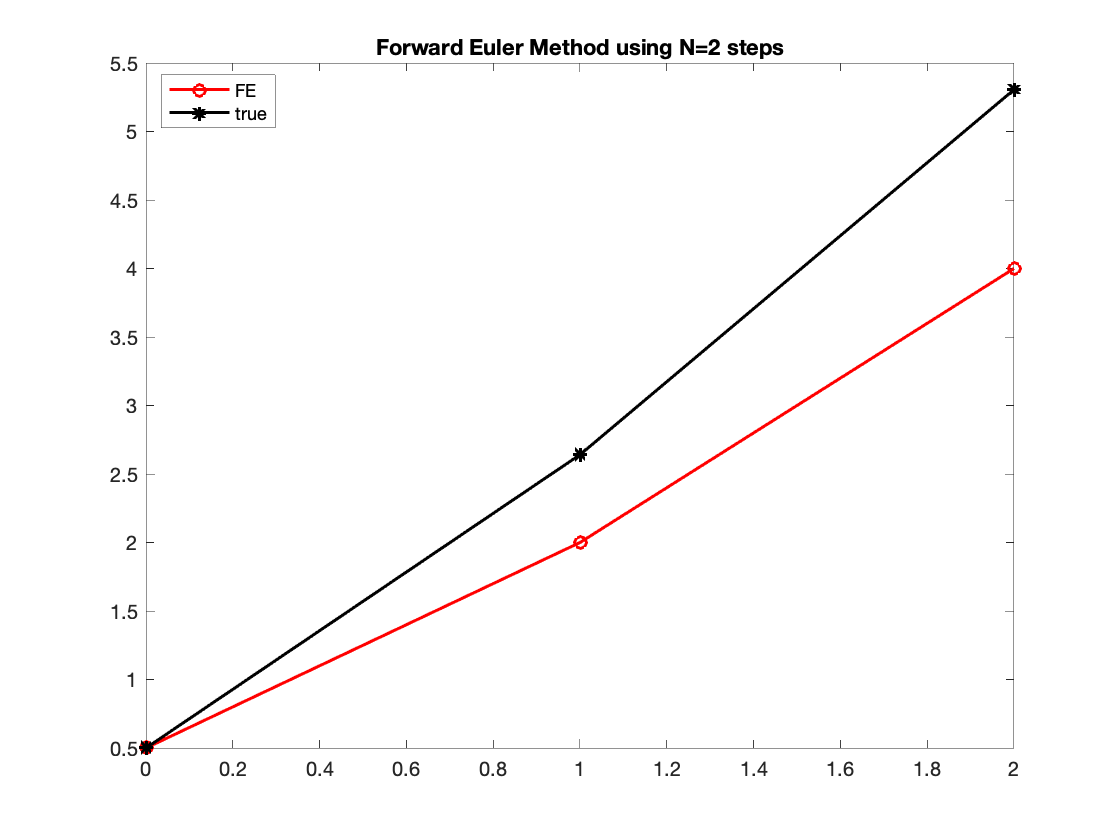

### **Algorithm (Forward Euler’s method)**:

To approximate the solution of the IVP 


$$\[
(IVP)\quad
\begin{cases}
y'(t)&=&f(t,y),&\quad a\le t\le b,\\
y(a)&=&\alpha.&
\end{cases}
\]$$


at equally spaced numbers in the interval $[a,b]$ with step size $h$: 

**    INPUT** endpoints $a, b$; initial value $\alpha$; step size $h$; function $f(t,y)$.

**    OUTPUT **approximation $\omega$ to $y$ at the mesh points $t$.				

**    Step 1 **Set $N=(b-a)/h$;

                        $t=a$;

                        $\omega=\alpha$.

**    Step 2 **For $i=1,2,\cdots, N$ do Step 3.

**    Step 3** Set $\omega=\omega+hf(t,\omega)$;

                        $t=t+h$.

**    Step 4** Output( $t$, $\omega$). Stop.

**What to do?**

Finish the function for Forward Euler's method in file "**FE.m**".

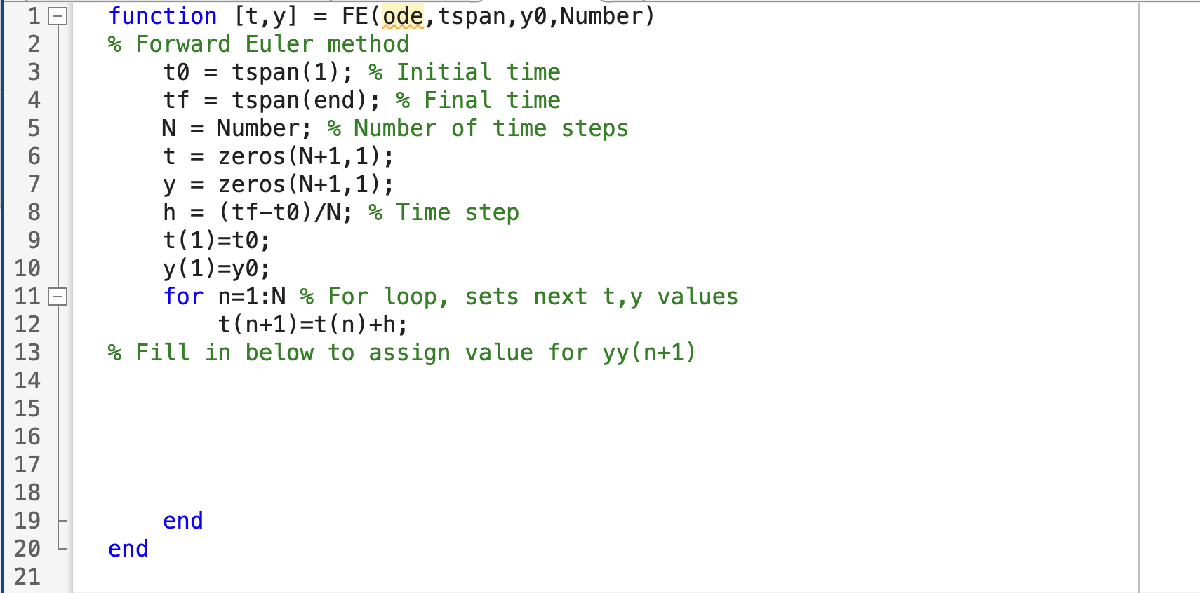							

### Error bound of Forward Euler’s method 

**Theorem 1** Suppose: 

        (1) $f$ is continuous and Lipschitz in $y$ with constant $L$ on $D=\{(t,y)|a\leq t \leq b,-\infty <y< \infty \}$,

        (2) there is a constant $M > 0$ s.t. $|y''(t)| \leq M$ for any $t \in [a,b]$.

Let $y(t)$ be the unique solution to 

	
$$\[
\begin{cases}
y'(t)&=&f(t,y),&\quad a\le t\le b,\\
y(a)&=&\alpha,&
\end{cases}
\]$$
			

and 


$$\[
\begin{cases}
\omega_0&=&&\alpha,&\\
\omega_{i+1}&=&&\omega_i+h f(t_i,\omega_i),&i=0,1,\cdots,N-1.
\end{cases}
\]$$
			

Then the error at each timestep $t_i$ is bounded as follows 


$$|y(t_i)-\omega_i| \leq  h \frac{M}{2L}[e^{L(t_i-a)}-1], \qquad i=0, 1,\dots, N.$$
			 

### Error bound for Forward Euler’s method and round-off error 		

**Theorem 2 **Let $y(t)$ be the unique solution to the IVP


$$\[
\begin{cases}
y'(t)&=&f(t,y),&\quad a\le t\le b,\\
y(a)&=&\alpha,&
\end{cases}
\]$$
			

and $\omega_i  (i = 0,1, \dots, N)$ are obtained from the pertubed IVP


$$\[
\begin{cases}
\omega_0&=&&\alpha + \delta_0,&\\
\omega_{i+1}&=&&\omega_i+h f(t_i,\omega_i) + \delta_{i+1},&i=0,1,\cdots,N-1.
\end{cases}
\]$$
			

If $\delta_i < \delta$ for each $i = 0,1,\dots,N$ and the hypotheses of the previous Theorem hold. Then 


$$|y(t_i)-\omega_i| \leq \frac{1}{L} \left(\frac{hM}{2}+\frac{\delta}{h}\right)[e^{L(t_i-a)}-1]+|\delta_0|\,e^{L(t_i-a)}, \quad i=0, 1,\dots, N.$$


**Remark**: when $\frac{hM}{2} = \frac{\delta}{h}$, i.e. $h = \sqrt{\frac{2\delta}{M}}$, the error is minimized. 			

## **3. **Higher-order Taylor methods 

### **Taylor method of order n:**		 


$$\[
\begin{cases}
\omega_0&=&&\alpha,&\\
\omega_{i+1}&=&&\omega_i+h T_n(t_i,\omega_i), &i=0,1,\cdots,N-1.
\end{cases}
\]$$
	 			

where 		


$$T_n(t_i,\omega_i) =f(t_i,\omega_i)+\frac{h}{2} f'(t_i,\omega_i)+\cdots+\frac{h^{n-1}}{n!}\,f^{(n-1)}(t_i,\omega_i).$$
	 

Notice, the derivative of $f$ is the total derivate of $f$ w.r.t. $t$. For example, $f'(t,y) = f_t + f_y y'(t) = f_t + f_y f$.

**Example:**

Taylor method of order 1:	


$$T_1(t_i,\omega_i) =f(t_i,\omega_i)$$
	

Taylor method of order 2:					 


$$T_2(t_i,\omega_i) =f(t_i,\omega_i)+\frac{h}{2} f'(t_i,\omega_i)$$


Taylor method of order 3:							


$$T_3(t_i,\omega_i) =f(t_i,\omega_i)+\frac{h}{2} f'(t_i,\omega_i)+\frac{h^{2}}{6}\,f''(t_i,\omega_i).$$


### **local truncation error**			

**Definition**:  The difference method


$$\[
\begin{cases}
\omega_0&=&&\alpha,&\\
\omega_{i+1}&=&&\omega_i+h \phi(t_i,\omega_i), &i=0,1,\cdots,N-1.
\end{cases}
\]$$
	 				

has **local truncation error**


$$\tau_{i+1}(h)=\frac{y_{i+1}-(y_i+h\phi(t_i,y_i))}{h}=\frac{y_{i+1}-y_i}{h}-\phi(t_i,y_i)$$


for each $i=0,1, \cdots, N-1$.				

**Remark:**

- 
$$y_{i+1}=y_i+h\,\phi(t_i,y_i)+ {h\,\tau_{i+1}(h)}$$


- For Euler's method $\tau_{i+1}=h\,\frac{y''(\xi_i)}{2}$,

- $\omega_0=y_0$ implies $\tau_1=\frac{y_1-\omega_1}{h}$.  If $\omega_i=y_i$, then $\tau_{i+1}=\frac{y_{i+1}-\omega_{i+1}}{h}$.

**Example 1**: Consider the following initial-value problem 		


$$\[
\begin{cases}
y'&=&y-t^2+1,&\quad 0\le t\le 2,\\
y(0)&=&0.5.&
\end{cases}
\]$$
			

Use Taylor methods of order 2 to approximate $y(2)$ with $h=1$.				

**Answer  **Taylor methods of order 2:


$$\[
\begin{cases}
\omega_0&=&&\alpha,&\\
\omega_{i+1}&=&&\omega_i+h T_2(t_i,\omega_i), &i=0,1,\cdots,N-1.
\end{cases}
\]$$
	 		


$$T_2(t_i,\omega_i) =f(t_i,\omega_i)+\frac{h}{2} f'(t_i,\omega_i)$$
					

% The codes are hidden here. Try with the finished app for the results. And the 
% results should look the red curve as follows.

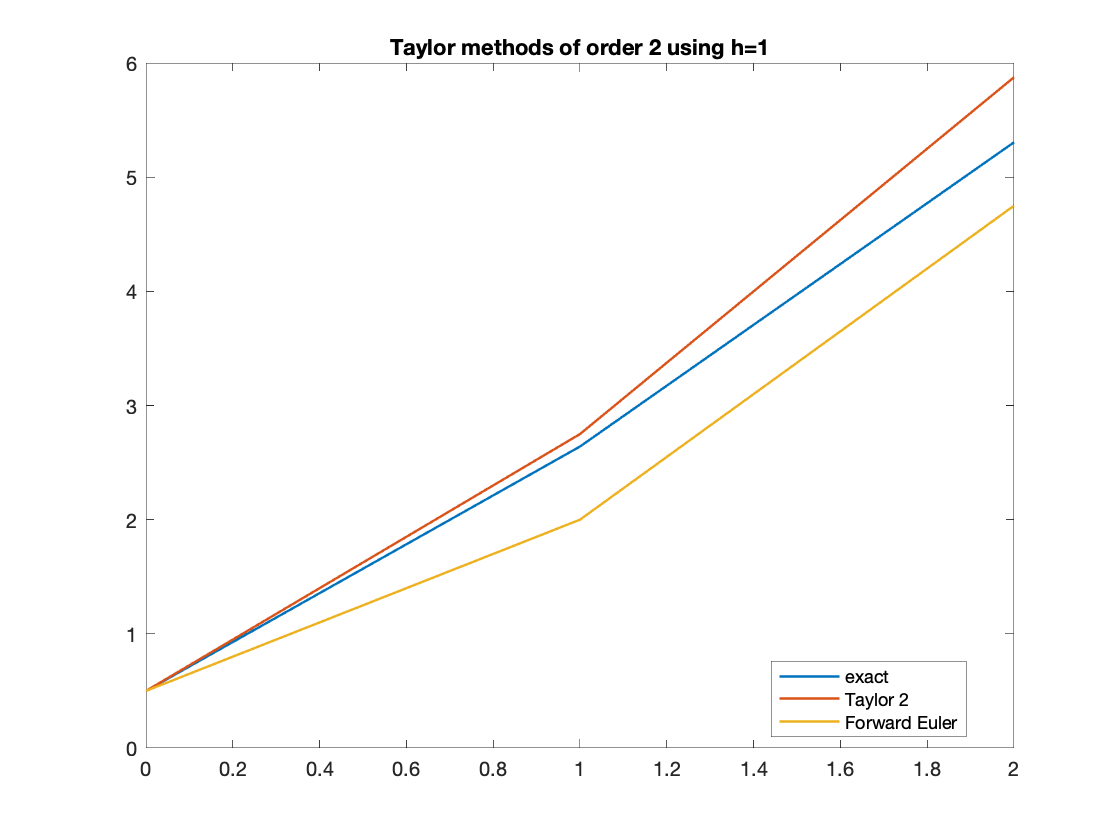			

**Example 2**: Consider the following initial-value problem


$$\[
\begin{cases}
y'&=&y-t^2+1,&\quad 0\le t\le 2,\\
y(0)&=&0.5.
\end{cases}
\]$$


Use Taylor methods of order 3 to approximate $y(2)$ with $h=1$.

**Answer**


$$\[
\begin{cases}
\omega_0&=&&\alpha,&\\
\omega_{i+1}&=&&\omega_i+h T_3(t_i,\omega_i), &i=0,1,\cdots,N-1.
\end{cases}
\]$$
	 		


$$T_3(t_i,\omega_i) =f(t_i,\omega_i)+\frac{h}{2} f'(t_i,\omega_i)+\frac{h^{2}}{6}\,f''(t_i,\omega_i).$$


% The codes are hidden here. Try with the finished app for the results. And the 
% results should look the blue curve as follows.

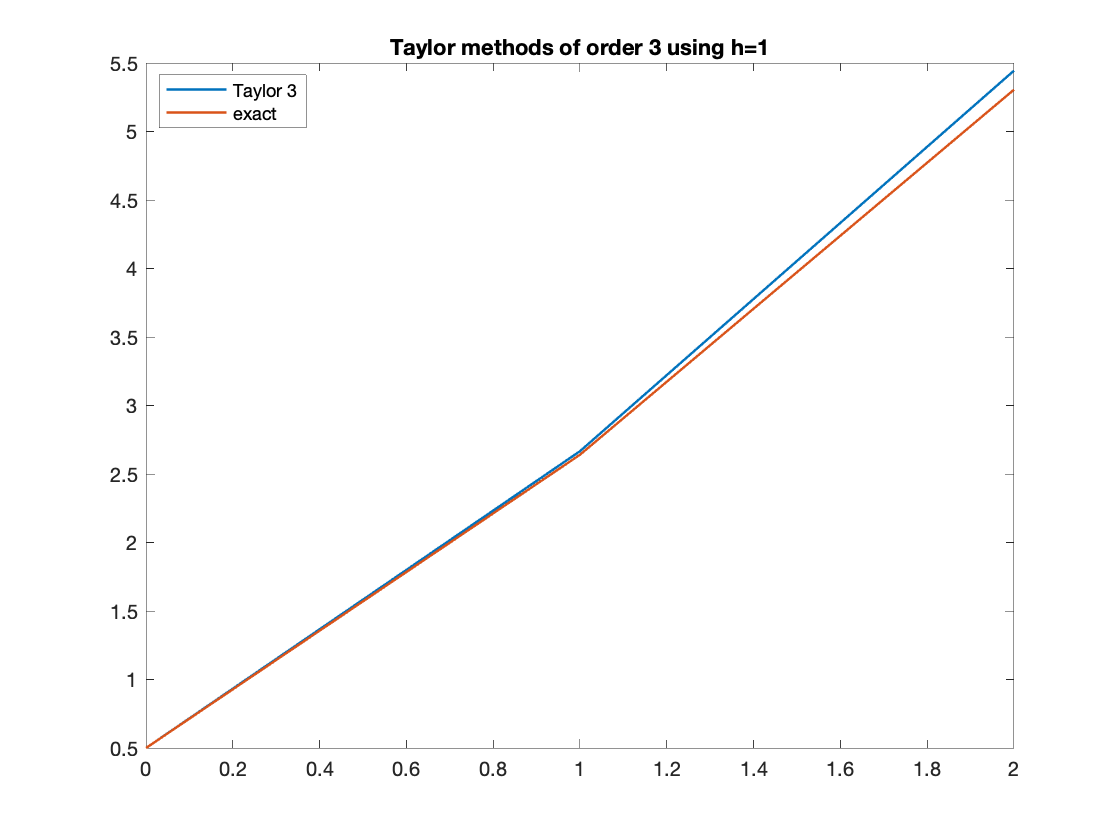				

### **Advantage and Disadvantage** of Taylor's method 

**Taylor's method of order **$n$**:**		 


$$\[
\begin{cases}
\omega_0&=&&\alpha,&\\
\omega_{i+1}&=&&\omega_i+h T_n(t_i,\omega_i), &i=0,1,\cdots,N-1.
\end{cases}
\]$$
	 			

where 		


$$T_n(t_i,\omega_i) =f(t_i,\omega_i)+\frac{h}{2} f'(t_i,\omega_i)+\cdots+\frac{h^{n-1}}{n!}\,f^{(n-1)}(t_i,\omega_i).$$


**Advantage:** high-order local truncation error, $\tau_{i+1}(h)=\mathcal{O}(h^n)$.

**Disadvantage:** need to compute and evaluate the derivatives $f', f'', \cdots, f^{(n-1)}$ at $(t_i, \omega_i)$.

**What to do?**

Finish the function for Forward Euler's method in file "**Taylor.m**".			

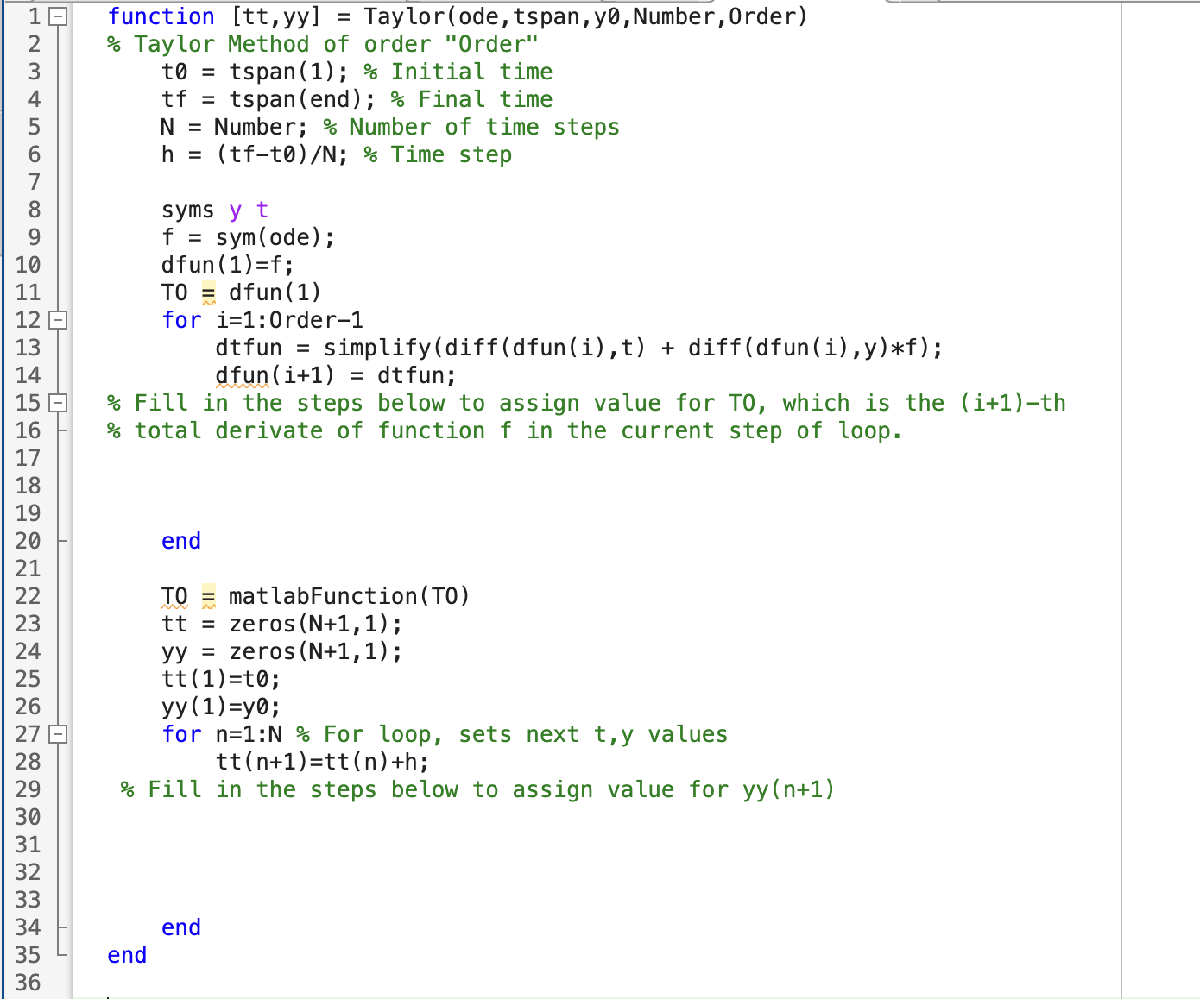			

## 4. Runge-Kutta (RK) Methods				

**Motivation**: obtain methods with high-order local truncation error without computing  derivatives of $f$.		

**Idea**: approximate	


$$T_n(t,y)=f(t_i,\omega_i)+\frac{h}{2}\,f'(t_i,\omega_i)+\cdots+\frac{h^{n-1}}{n!}\,f^{(n-1)}(t_i,\omega_i)$$
		

by evaluating $f$ at different points.

### Taylor's Theorem in two variables (2D Taylor expansion)

**Theorem**: Suppose that $f$ and all its derivatives of order less than or equal to $n+1$ are continuous on $D=\{(t, y)|a \leq t \leq b, c \leq y \leq d\}$, and let $(t_0, y_0)\in D$. For every $(t, y)\in D$, there exists $\xi$ between $t$ and $t_0$ and $\mu$ between $y$ and $y_0$ with


$$f(t,y)=P_n(t,y)+R_n(t,y),$$
 

where, the *2D Taylor expansion* is


$$\begin{array}{rcl}
P_n(t,y)&=&f(t_0,y_0)+\Big[{(t-t_0)\frac{\partial f}{\partial t}(t_0,y_0)}+{(y-y_0)\frac{\partial f}{\partial y}(t_0,y_0)}\Big]\\
&&+\Big[{\frac{(t-t_0)^2}{2}\frac{\partial^2 f}{\partial^2 t^2}(t_0,y_0)}+{(t-t_0)(y-y_0)\frac{\partial^2 f}{\partial t\partial y}(t_0,y_0)} +{\frac{(y-y_0)^2}{2}\frac{\partial^2 f}{\partial y^2}(t_0,y_0)}\Big]\\
 &&+\cdots\\
&&+\Big[{\frac{1}{n!}\sum_{j=0}^n {n\choose j} (t-t_0)^{n-j}(y-y_0)^j\frac{\partial^n f}{\partial t^{n-j} \partial y^j}(t_0,y_0)}\Big], 
\end{array}$$


and the *residual* is 


$$R_n(t,y)=\frac{1}{(n+1)!}\sum_{j=0}^{n+1} { n+1\choose j}(t-t_0)^{n+1-j}(y-y_0)^j\frac{\partial^{n+1} f}{\partial t^{n+1-j}\partial y^j}(\xi,\mu).$$
		

**Remark:** If we define


$$g_k(t,y)=\frac{1}{k!}\sum_{j=0}^k {k\choose j} (t-t_0)^{k-j}(y-y_0)^j\frac{\partial^k f}{\partial t^{k-j}\,\partial y^j}(t_0,y_0),$$


then


$$\begin{array}{rcl}
P_n(t,y)&=&g_0(t,y)+g_1(t,y)+\cdots+g_n(t,y),\\
R_n(t,y)&=&g_{n+1}(\xi,\mu), 
\end{array}$$


and


$$f(t,y)=g_0(t,y)+g_1(t,y)+\cdots+g_n(t,y)+g_{n+1}(\xi,\mu).$$


### Derivation of a second-order RK method							

Recall the second-order Taylor's method:


$$\omega_{i+1}=\omega_i+h\,T_2(t_i,\omega_i),\;\;\textrm{ where }T_2(t_i,\omega_i)=f(t_i,\omega_i)+\frac{f'(t_i,\omega_i)}{2}\,h.$$


Approximate $T_2(t,y)$ by $a_1f(t+\alpha_1,y+\beta_1)$, where $a_1, \alpha_1, \beta_1$ are chosen so that local truncation error is $\mathcal{O}(h^2)$.

- rewrite $T_2(t,y)$ in terms of $f$ and its partial derivatives.

- use Taylor's theorem in two variables to expand $a_1f(t+\alpha_1,y+\beta_1)$ at the point $(t,y)$.

- match the coefficients of correspondent terms.

Following above three steps, we get

 
$$a_1=1, \;\;\alpha_1=\frac{h}{2},\;\;\beta_1= \frac{h}{2}f(t,y).$$


#### Midpoint method:


$$\omega_0=\alpha,$$



$$\omega_{i+1}=\omega_i+h\,f\bigl(t_i+\frac{h}{2},\omega_i+\frac{h}{2}f(t_i,\omega_i)\bigr),\;\;i=0,1,\cdots, N-1.$$


**What to do?**

Finish the function for Forward Euler's method in file "**RK2Midpoint.m**".		

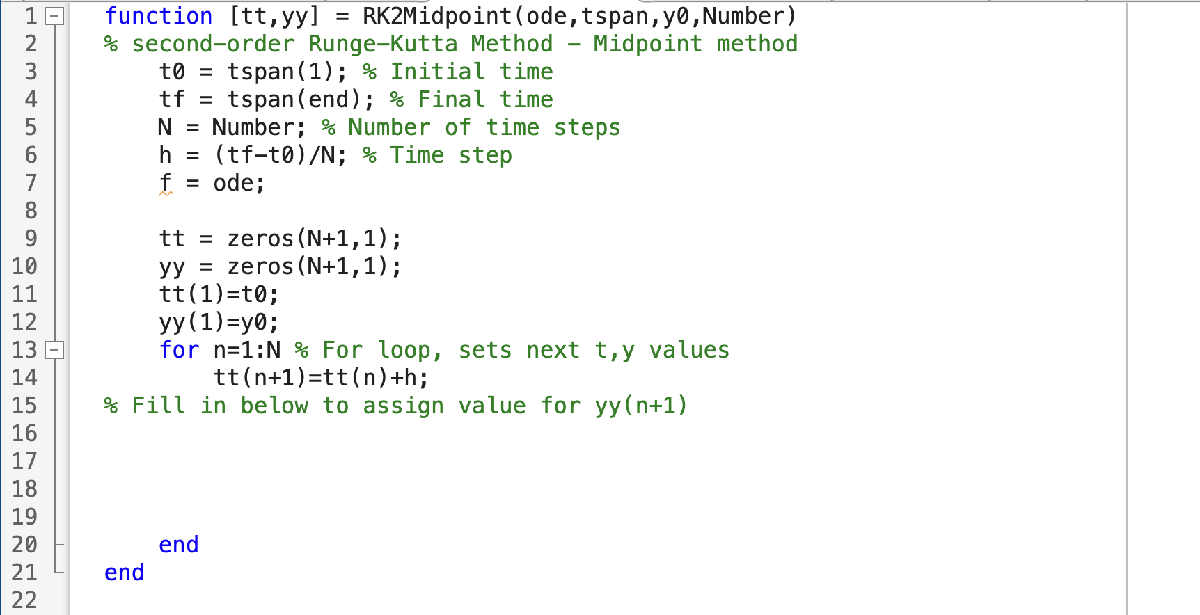									

**Example 1**: Consider the following initial-value problem 		


$$\[
\begin{cases}
y'&=&y-t^2+1,&\quad 0\le t\le 2,\\
y(0)&=&0.5.&
\end{cases}
\]$$
			

Use midpoint method to approximate $y(2)$ with $h=1$.				

**Answer**				

% The codes are hidden here. Try with the finished app for the results. And the 
% results should look the red curve as follows.

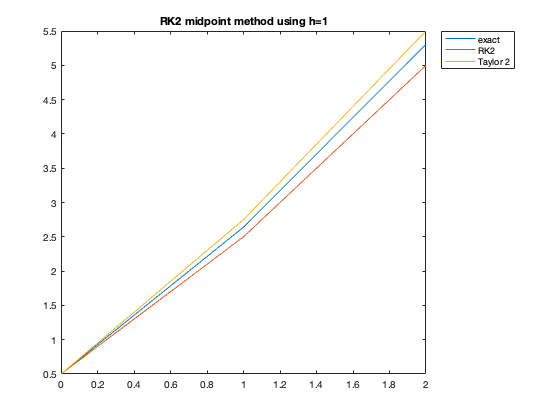

#### Other second-order RK methos

We can also approximate $T_2(t,y)$ by $a_1 f(t,y)+a_2 f(t+\alpha_1, y+\beta_1)$.

**Modified Euler method**: ( $a_1=\frac{1}{2}, a_2=\frac{1}{2}, \alpha_1=h, \beta_1=hf(t,y)$ )


$$\omega_{i+1}=\omega_i+\frac{h}{2} \bigl[ f(t_i,\omega_i)+f\bigl(t_i+h, \omega_i+ hf(t_i,\omega_i)\bigr)\bigr].$$


**Heun's method**: ( $a_1=\frac{1}{4},\,a_2=\frac{3}{4},\,\alpha_1=\frac{2}{3}h,\,\beta_1=\frac{2}{3}hf(t,y)$ )


$$\omega_{i+1}=\omega_i+\frac{h}{4}\,\bigl[f(t_i,\omega_i)+3f\bigl(t_i+\frac{2}{3}h,\omega_i+\frac{2}{3}hf(t_i,\omega_i)\bigr)\bigr].$$


**What to do?**

Finish the function for Forward Euler's method in file "**RK2ModEuler.m**" and "**RK2Heun.m**".	

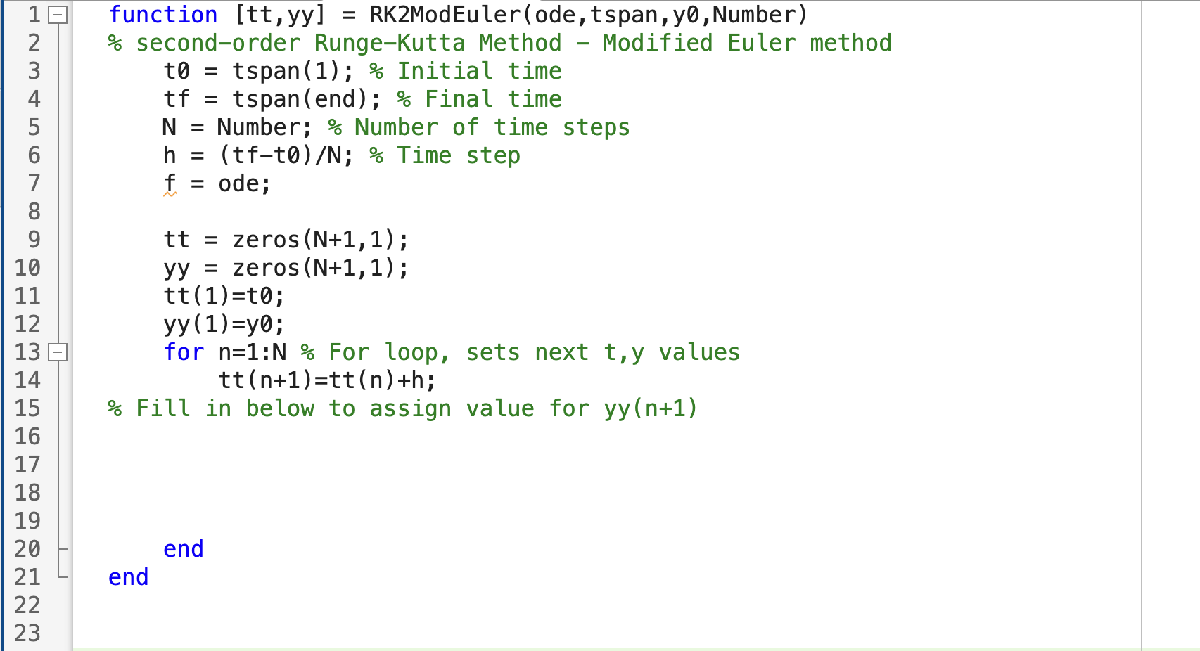

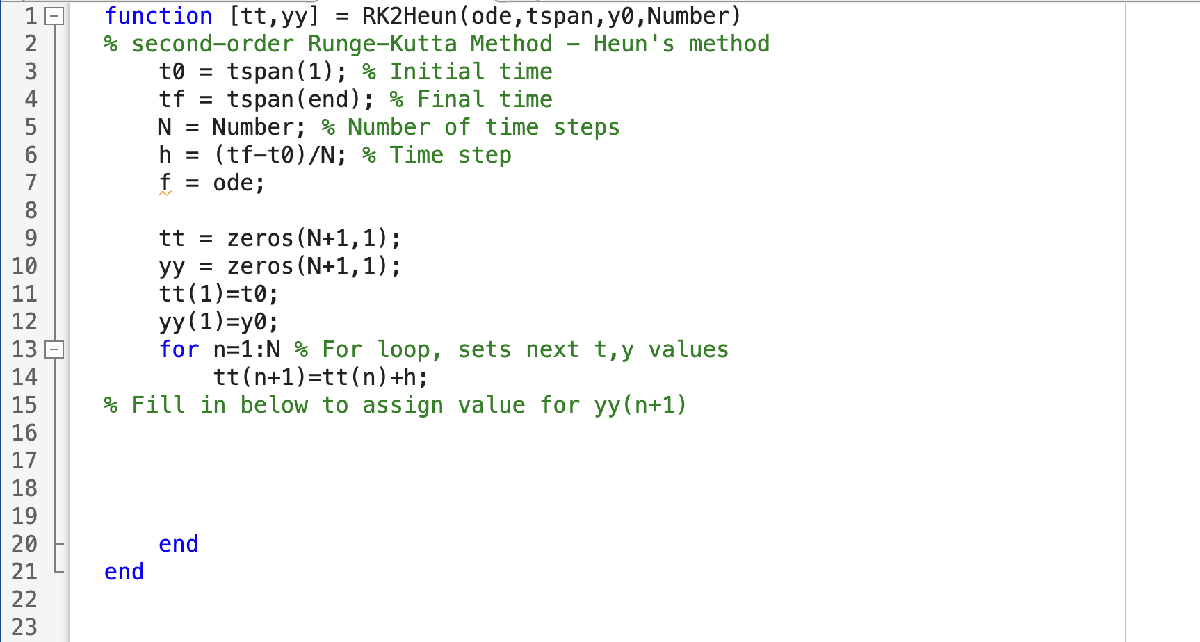		

### The most popular RK methods (RK4)	 	

**RK method of order four**:


$$\begin{array}{rcl}
\omega_0&=&\alpha,\\
K_1&=&hf(t_i,\omega_i),\\
K_2&=&hf(t_i+\frac{h}{2}, \omega_i+\frac{K_1}{2}),\\
K_3&=&hf(t_i+\frac{h}{2},\omega_i+\frac{K_2}{2}),\\
K_4&=&hf(t_i+h, \omega_i+K_3),\\
\omega_{i+1}&=&\omega_i+\frac{1}{6}(K_1+2K_2+2K_3+K_4).
\end{array}$$


**Remark**: midpoint method: $\omega_{i+1}=\omega_i+K_2.$

**What to do?**

Finish the function for Forward Euler's method in file "**RK4.m**".		

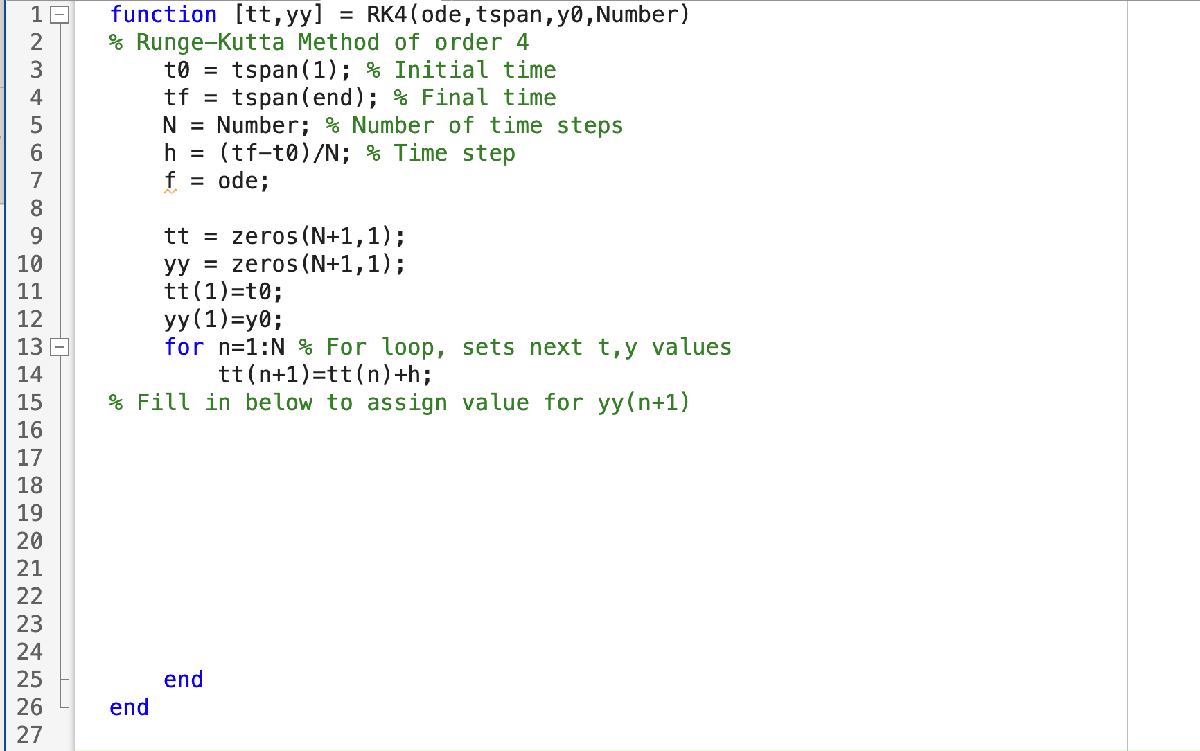	

**Example 2**: Consider the following initial-value problem 		


$$\[
\begin{cases}
y'&=&y-t^2+1,&\quad 0\le t\le 2,\\
y(0)&=&0.5.&
\end{cases}
\]$$
			

Use Runge-Kutta method of order 4 to approximate $y(2)$ with $h=1$.				

**Answer**				

% The codes are hidden here. Try with the finished app for the results. And the 
% results should look the red curve as follows.

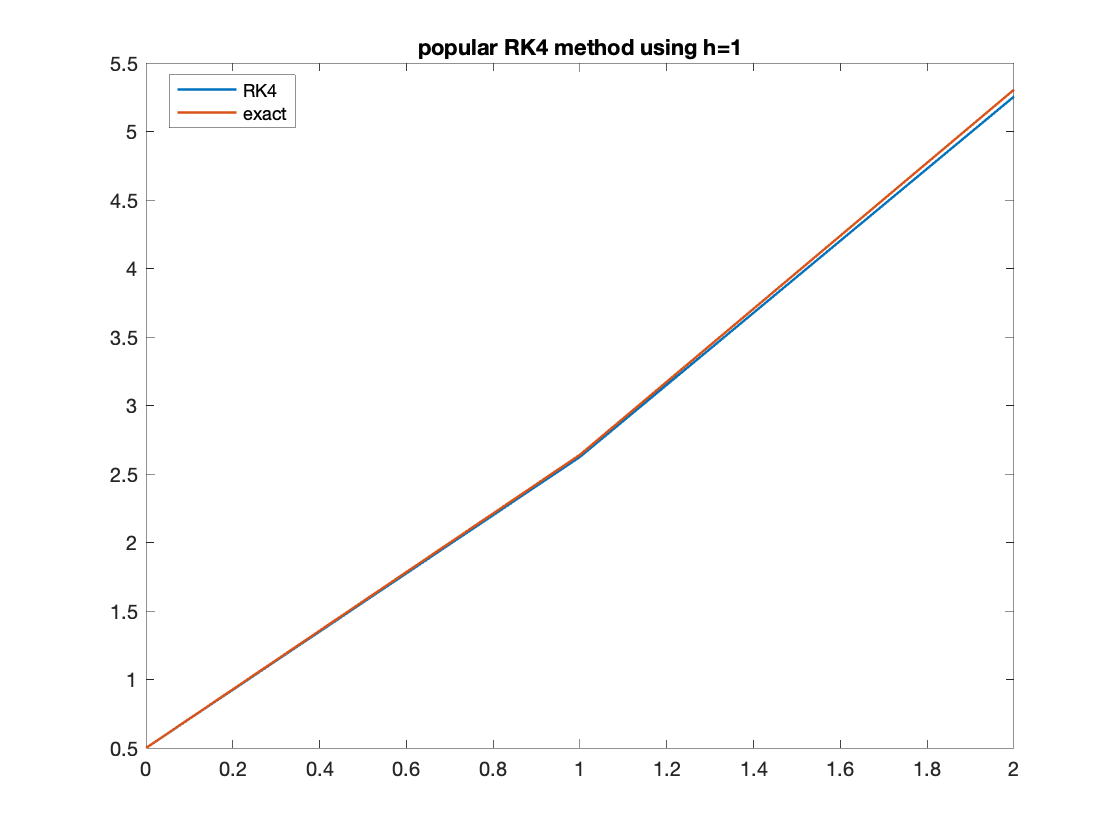

Next, one could check the order of convergence of RK4 method by increasing the number of $N$ or by decreasing the size of step size $h$ and see how the error changes. Here is the log-log plot of the errors. And the slope of RK4 error is 4, which indicates the order and means $error_h \sim \mathcal{O}(h^4)$. When the size of $h$ is reduced to a half, the error is expected to be reduced to a sixteenth, since $\left(\frac{1}{2}\right)^4 = \frac{1}{16}$.